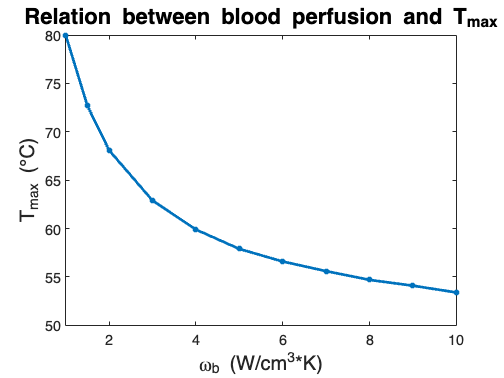

wt = [1 1.5 2 3 4 5 6 7 8 9 10];
T = [80.0 72.7 68.1 62.9 59.9 57.9 56.6 55.6 54.7 54.1 53.4];
figure
plot(wt,T,'*-','LineWidth',3)
set(gca,'FontSize',16)
xlabel('\omega_b (W/cm^3*K)')
title('Relation between blood perfusion and T_{max}','FontSize',25)
ylabel(['T_{max} (' char(176) 'C)'],'FontSize',22)
xlabel("\omega_b (W/cm^3*K)",'FontSize',22)
xlim([1 10])

%legend("d = 0 cm","d = 1 cm","d = 2 cm","d = 3 cm","d = 4 cm")

# Intersection graphs

## necrotic core diameter

Tresults_necrotic_1cm = load('Tresults_necrotic_1cm.mat');
Tresults_XZ_default = load('Tresults_XZ_default.mat');
Tresults_necrotic_2cm = load('Tresults_necrotic_2cm.mat');
Tresults_necrotic_3cm = load('Tresults_necrotic_3cm.mat');
Tresults_necrotic_4cm = load('Tresults_necrotic_4cm.mat');


spread = Tresults_XZ_default.Tresults(:,201);
heatspread = [Tresults_XZ_default.Xnodes Tresults_XZ_default.Ynodes spread];
for i = 1:length(heatspread(:,2))
    if heatspread(i,2) >= 4.03 || heatspread(i,2) <= 3.97
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);

%%%%%% 1cm %%%%%
%Tresults_XZ_optimize = load('Tresults_XZ_optimize.mat')
spread1 = Tresults_necrotic_1cm.Tresults(:,201);
heatspread1_default = [Tresults_necrotic_1cm.Xnodes Tresults_necrotic_1cm.Ynodes spread1];
for i = 1:length(heatspread1_default(:,2))
    if heatspread1_default(i,2) >= 4.03 || heatspread1_default(i,2) <= 3.97
        heatspread1_default(i,2) = 0;
    end
end
heatspread1_default(any(heatspread1_default(:,2)==0,2),:) = [];
heatspread1_default = sortrows(heatspread1_default,1);

%%%%%% 2cm %%%%%
%Tresults_XZ_optimize = load('Tresults_XZ_optimize.mat')
spread2 = Tresults_necrotic_2cm.Tresults(:,201);
heatspread2_default = [Tresults_necrotic_2cm.Xnodes Tresults_necrotic_2cm.Ynodes spread2];
for i = 1:length(heatspread2_default(:,2))
    if heatspread2_default(i,2) >= 4.03 || heatspread2_default(i,2) <= 3.97
        heatspread2_default(i,2) = 0;
    end
end
heatspread2_default(any(heatspread2_default(:,2)==0,2),:) = [];
heatspread2_default = sortrows(heatspread2_default,1);

%%%%%% 3cm %%%%%
spread3 = Tresults_necrotic_3cm.Tresults(:,201);
heatspread3 = [Tresults_necrotic_3cm.Xnodes Tresults_necrotic_3cm.Ynodes spread3];
for i = 1:length(heatspread3(:,2))
    if heatspread3(i,2) >= 4.03 || heatspread3(i,2) <= 3.97
        heatspread3(i,2) = 0;
    end
end
heatspread3(any(heatspread3(:,2)==0,2),:) = [];
heatspread3 = sortrows(heatspread3,1);

%%%%%% 4cm %%%%%
spread4 = Tresults_necrotic_4cm.Tresults(:,201);
heatspread4 = [Tresults_necrotic_4cm.Xnodes Tresults_necrotic_4cm.Ynodes spread4];
for i = 1:length(heatspread4(:,2))
    if heatspread4(i,2) >= 4.03 || heatspread4(i,2) <= 3.97
        heatspread4(i,2) = 0;
    end
end
heatspread4(any(heatspread4(:,2)==0,2),:) = [];
heatspread4 = sortrows(heatspread4,1);

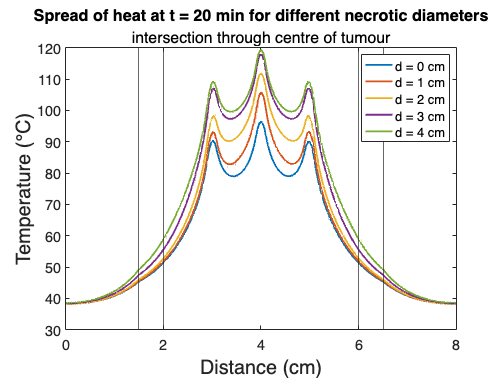


figure
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',2)
hold on 
plot(heatspread1_default(:,1),heatspread1_default(:,3),'-','Linewidth',2)
plot(heatspread2_default(:,1),heatspread2_default(:,3),'-','Linewidth',2)
plot(heatspread3(:,1),heatspread3(:,3),'-','Linewidth',2)
plot(heatspread4(:,1),heatspread4(:,3),'-','Linewidth',2)
xline(2);
xline(6);
xline(1.5);
xline(6.5);
%yline(48,[2 6])
set(gca,'FontSize',16)
title("Spread of heat at t = 20 min for different necrotic diameters",'FontSize',18)
txt = {'intersection through centre of tumour'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Distance (cm)",'FontSize',22)
legend("d = 0 cm","d = 1 cm","d = 2 cm","d = 3 cm","d = 4 cm")

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

%ylim([37 38])

## wb functions

Tresults_wb_min = load('Tresults_XZ_wb_lin.mat');
Tresults_XZ_default = load('Tresults_XZ_default.mat');
Tresults_wb_max = load('Tresults_XZ_wb_F.mat');


spread = Tresults_XZ_default.Tresults(:,201);
heatspread = [Tresults_XZ_default.Xnodes Tresults_XZ_default.Ynodes spread];
for i = 1:length(heatspread(:,2))
    if heatspread(i,2) >= 4.03 || heatspread(i,2) <= 3.97
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);

%%%%%% min %%%%%
%Tresults_XZ_optimize = load('Tresults_XZ_optimize.mat')
spread2 = Tresults_wb_min.Tresults(:,201);
heatspread2_default = [Tresults_wb_min.Xnodes Tresults_wb_min.Ynodes spread2];
for i = 1:length(heatspread2_default(:,2))
    if heatspread2_default(i,2) >= 4.03 || heatspread2_default(i,2) <= 3.97
        heatspread2_default(i,2) = 0;
    end
end
heatspread2_default(any(heatspread2_default(:,2)==0,2),:) = [];
heatspread2_default = sortrows(heatspread2_default,1);

%%%%%% max %%%%%
spread3 = Tresults_wb_max.Tresults(:,201);
heatspread3 = [Tresults_wb_max.Xnodes Tresults_wb_max.Ynodes spread3];
for i = 1:length(heatspread3(:,2))
    if heatspread3(i,2) >= 4.03 || heatspread3(i,2) <= 3.97
        heatspread3(i,2) = 0;
    end
end
heatspread3(any(heatspread3(:,2)==0,2),:) = [];
heatspread3 = sortrows(heatspread3,1);

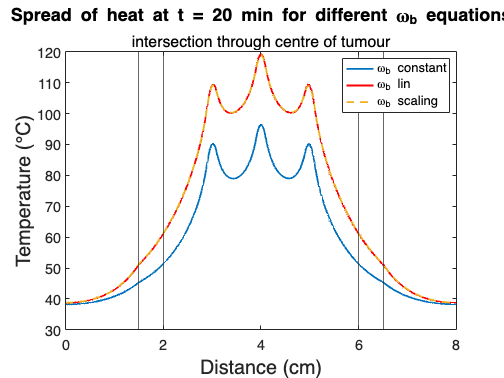


figure
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',2)
hold on 
plot(heatspread2_default(:,1),heatspread2_default(:,3),'-','Linewidth',2,'Color','r')
plot(heatspread3(:,1),heatspread3(:,3),'-','Linewidth',2,'LineStyle','--')
xline(2);
xline(6);
xline(1.5);
xline(6.5);
%yline(48,[2 6])
set(gca,'FontSize',16)
title("Spread of heat at t = 20 min for different \omega_b equations",'FontSize',20)
txt = {'intersection through centre of tumour'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Distance (cm)",'FontSize',22)
legend("\omega_b constant","\omega_b lin","\omega_b scaling")

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

%ylim([37 38])

## wb min max

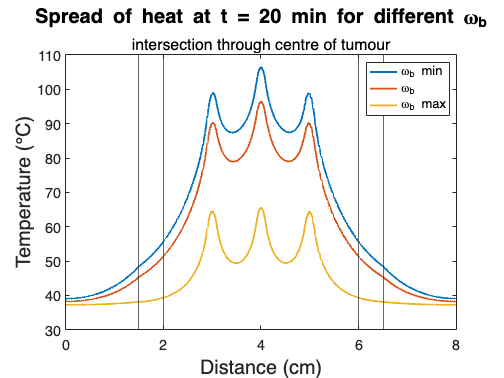

Tresults_wb_min = load('Tresults_wb_min.mat');
Tresults_XZ_default = load('Tresults_XZ_default.mat');
Tresults_wb_max = load('Tresults_wb_max.mat');


spread = Tresults_XZ_default.Tresults(:,201);
heatspread = [Tresults_XZ_default.Xnodes Tresults_XZ_default.Ynodes spread];
for i = 1:length(heatspread(:,2))
    if heatspread(i,2) >= 4.03 || heatspread(i,2) <= 3.97
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);

%%%%%% min %%%%%
%Tresults_XZ_optimize = load('Tresults_XZ_optimize.mat')
spread2 = Tresults_wb_min.Tresults(:,201);
heatspread2_default = [Tresults_wb_min.Xnodes Tresults_wb_min.Ynodes spread2];
for i = 1:length(heatspread2_default(:,2))
    if heatspread2_default(i,2) >= 4.03 || heatspread2_default(i,2) <= 3.97
        heatspread2_default(i,2) = 0;
    end
end
heatspread2_default(any(heatspread2_default(:,2)==0,2),:) = [];
heatspread2_default = sortrows(heatspread2_default,1);

%%%%%% max %%%%%
spread3 = Tresults_wb_max.Tresults(:,201);
heatspread3 = [Tresults_wb_max.Xnodes Tresults_wb_max.Ynodes spread3];
for i = 1:length(heatspread3(:,2))
    if heatspread3(i,2) >= 4.03 || heatspread3(i,2) <= 3.97
        heatspread3(i,2) = 0;
    end
end
heatspread3(any(heatspread3(:,2)==0,2),:) = [];
heatspread3 = sortrows(heatspread3,1);

figure
plot(heatspread2_default(:,1),heatspread2_default(:,3),'-','Linewidth',2)
hold on
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',2)
plot(heatspread3(:,1),heatspread3(:,3),'-','Linewidth',2)
xline(2);
xline(6);
xline(1.5);
xline(6.5);
%yline(48,[2 6])
set(gca,'FontSize',16)
title("Spread of heat at t = 20 min for different \omega_b",'FontSize',22)
txt = {'intersection through centre of tumour'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Distance (cm)",'FontSize',22)
legend("\omega_b min","\omega_b","\omega_b max")

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

%ylim([37 38])




## k min max

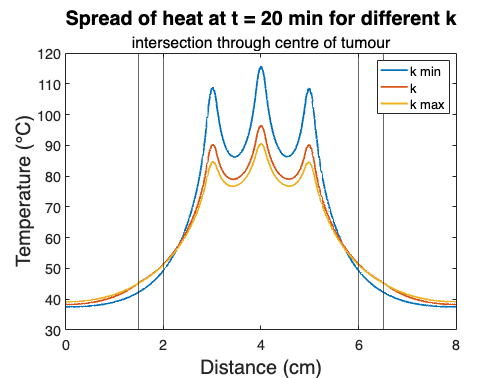

Tresults_k_min = load('Tresults_k_min.mat');
Tresults_XZ_default = load('Tresults_XZ_default.mat');
Tresults_k_max = load('Tresults_k_max.mat');


spread = Tresults_XZ_default.Tresults(:,201);
heatspread = [Tresults_XZ_default.Xnodes Tresults_XZ_default.Ynodes spread];
for i = 1:length(heatspread(:,2))
    if heatspread(i,2) >= 4.03 || heatspread(i,2) <= 3.97
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);

%%%%%% min %%%%%
%Tresults_XZ_optimize = load('Tresults_XZ_optimize.mat')
spread2 = Tresults_k_min.Tresults(:,201);
heatspread2_default = [Tresults_k_min.Xnodes Tresults_k_min.Ynodes spread2];
for i = 1:length(heatspread2_default(:,2))
    if heatspread2_default(i,2) >= 4.03 || heatspread2_default(i,2) <= 3.97
        heatspread2_default(i,2) = 0;
    end
end
heatspread2_default(any(heatspread2_default(:,2)==0,2),:) = [];
heatspread2_default = sortrows(heatspread2_default,1);

%%%%%% max %%%%%
spread3 = Tresults_k_max.Tresults(:,201);
heatspread3 = [Tresults_k_max.Xnodes Tresults_k_max.Ynodes spread3];
for i = 1:length(heatspread3(:,2))
    if heatspread3(i,2) >= 4.03 || heatspread3(i,2) <= 3.97
        heatspread3(i,2) = 0;
    end
end
heatspread3(any(heatspread3(:,2)==0,2),:) = [];
heatspread3 = sortrows(heatspread3,1);

figure
plot(heatspread2_default(:,1),heatspread2_default(:,3),'-','Linewidth',2)
hold on
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',2)
plot(heatspread3(:,1),heatspread3(:,3),'-','Linewidth',2)
xline(2);
xline(6);
xline(1.5);
xline(6.5);
%yline(48,[2 6])
set(gca,'FontSize',16)
title("Spread of heat at t = 20 min for different k",'FontSize',22)
txt = {'intersection through centre of tumour'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Distance (cm)",'FontSize',22)
legend("k min","k","k max")

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

%ylim([37 38])




## QNP min max

Tresults_QNP_min = load('Tresults_QNP_min.mat');
Tresults_XZ_default = load('Tresults_XZ_default.mat');
Tresults_QNP_max = load('Tresults_QNP_max.mat');


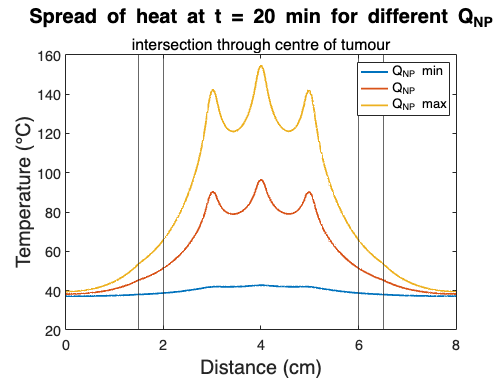


spread = Tresults_XZ_default.Tresults(:,201);
heatspread = [Tresults_XZ_default.Xnodes Tresults_XZ_default.Ynodes spread];
for i = 1:length(heatspread(:,2))
    if heatspread(i,2) >= 4.03 || heatspread(i,2) <= 3.97
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);

%%%%%% min %%%%%
%Tresults_XZ_optimize = load('Tresults_XZ_optimize.mat')
spread2 = Tresults_QNP_min.Tresults(:,201);
heatspread2_default = [Tresults_QNP_min.Xnodes Tresults_QNP_min.Ynodes spread2];
for i = 1:length(heatspread2_default(:,2))
    if heatspread2_default(i,2) >= 4.03 || heatspread2_default(i,2) <= 3.97
        heatspread2_default(i,2) = 0;
    end
end
heatspread2_default(any(heatspread2_default(:,2)==0,2),:) = [];
heatspread2_default = sortrows(heatspread2_default,1);

%%%%%% max %%%%%
spread3 = Tresults_QNP_max.Tresults(:,201);
heatspread3 = [Tresults_QNP_max.Xnodes Tresults_QNP_max.Ynodes spread3];
for i = 1:length(heatspread3(:,2))
    if heatspread3(i,2) >= 4.03 || heatspread3(i,2) <= 3.97
        heatspread3(i,2) = 0;
    end
end
heatspread3(any(heatspread3(:,2)==0,2),:) = [];
heatspread3 = sortrows(heatspread3,1);

figure
plot(heatspread2_default(:,1),heatspread2_default(:,3),'-','Linewidth',2)
hold on
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',2)
plot(heatspread3(:,1),heatspread3(:,3),'-','Linewidth',2)
xline(2);
xline(6);
xline(1.5);
xline(6.5);
%yline(48,[2 6])
set(gca,'FontSize',16)
title("Spread of heat at t = 20 min for different Q_{NP}",'FontSize',22)
txt = {'intersection through centre of tumour'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Distance (cm)",'FontSize',22)
legend("Q_{NP} min","Q_{NP}","Q_{NP} max")

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

%ylim([37 38])


# Temperatures over time

## t min max

Tresults_t_min = load('Tresults_t_min.mat');
Tresults_wb_constant = load('Tresults_wb_constant.mat');
Tresults_t_max = load('Tresults_t_max.mat');

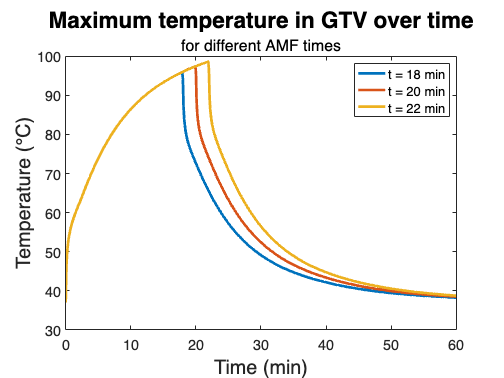


runData.timePoints = 0:0.1:90;
runData.timePointsX = 0:0.1:60;
figure
plot(runData.timePointsX,Tresults_t_min.solMax,'LineWidth',3)
hold on
plot(runData.timePoints,Tresults_wb_constant.solMax,'LineWidth',3)
plot(runData.timePointsX,Tresults_t_max.solMax,'LineWidth',3)
set(gca,'FontSize',16)
title('Maximum temperature in GTV over time','FontSize',25)
txt = {'for different AMF times'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("t = 18 min","t = 20 min","t = 22 min")
xlim([0 60])

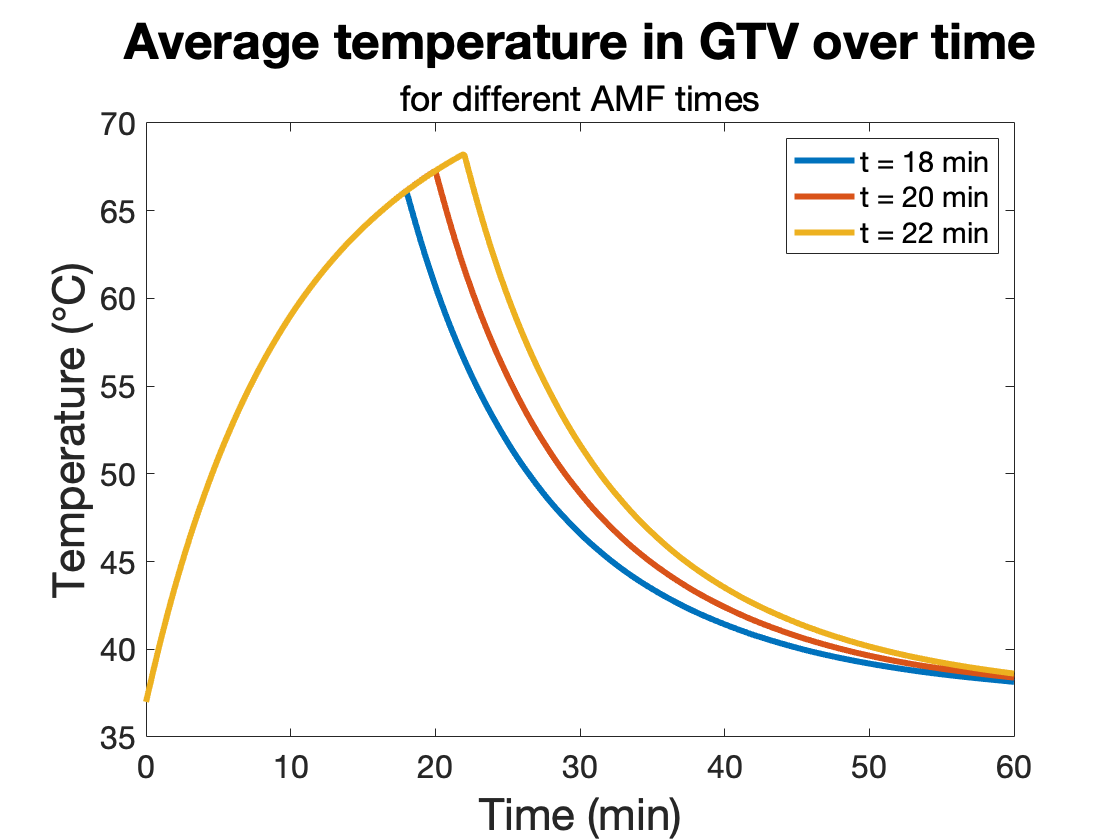

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

figure
plot(runData.timePointsX,Tresults_t_min.averageT,'LineWidth',3)
hold on
plot(runData.timePoints,Tresults_wb_constant.averageT,'LineWidth',3)
plot(runData.timePointsX,Tresults_t_max.averageT,'LineWidth',3)
set(gca,'FontSize',16)
title('Average temperature in GTV over time','FontSize',25)
txt = {'for different AMF times'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("t = 18 min","t = 20 min","t = 22 min")
xlim([0 60])

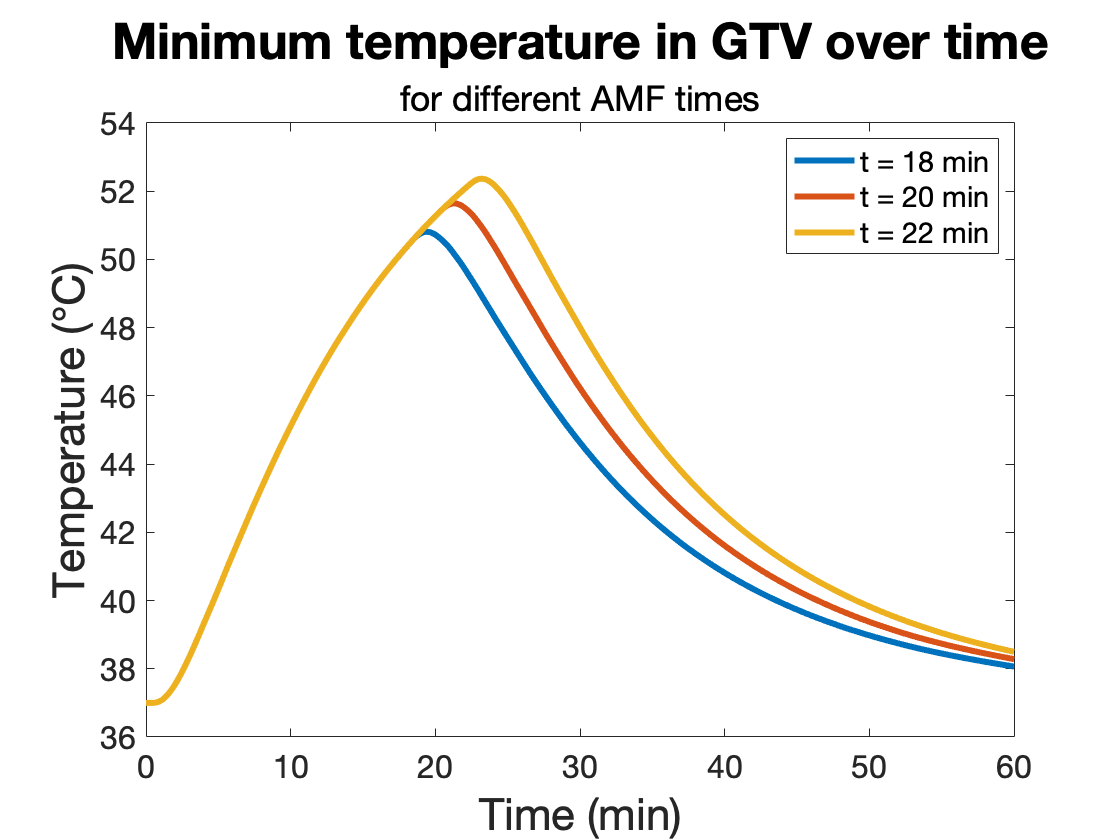


figure
plot(runData.timePointsX,Tresults_t_min.minT,'LineWidth',3)
hold on
plot(runData.timePoints,Tresults_wb_constant.minT,'LineWidth',3)
plot(runData.timePointsX,Tresults_t_max.minT,'LineWidth',3)
set(gca,'FontSize',16)
title('Minimum temperature in GTV over time','FontSize',25)
txt = {'for different AMF times'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("t = 18 min","t = 20 min","t = 22 min")
xlim([0 60])

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

## QNP min max

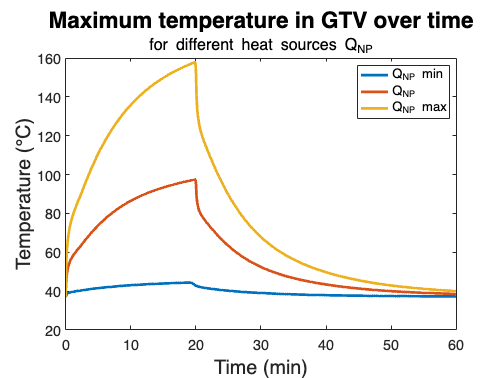

Tresults_QNP_min = load('Tresults_QNP_min.mat');
Tresults_wb_constant = load('Tresults_wb_constant.mat');
Tresults_QNP_max = load('Tresults_QNP_max.mat');

runData.timePointsX = 0:0.1:90;
figure
plot(runData.timePointsX,Tresults_QNP_min.solMax,'LineWidth',3)
hold on
plot(runData.timePointsX,Tresults_wb_constant.solMax,'LineWidth',3)
plot(runData.timePointsX,Tresults_QNP_max.solMax,'LineWidth',3)
set(gca,'FontSize',16)
title('Maximum temperature in GTV over time','FontSize',25)
txt = {'for different heat sources Q_{NP}'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("Q_{NP} min","Q_{NP}","Q_{NP} max")
xlim([0 60])

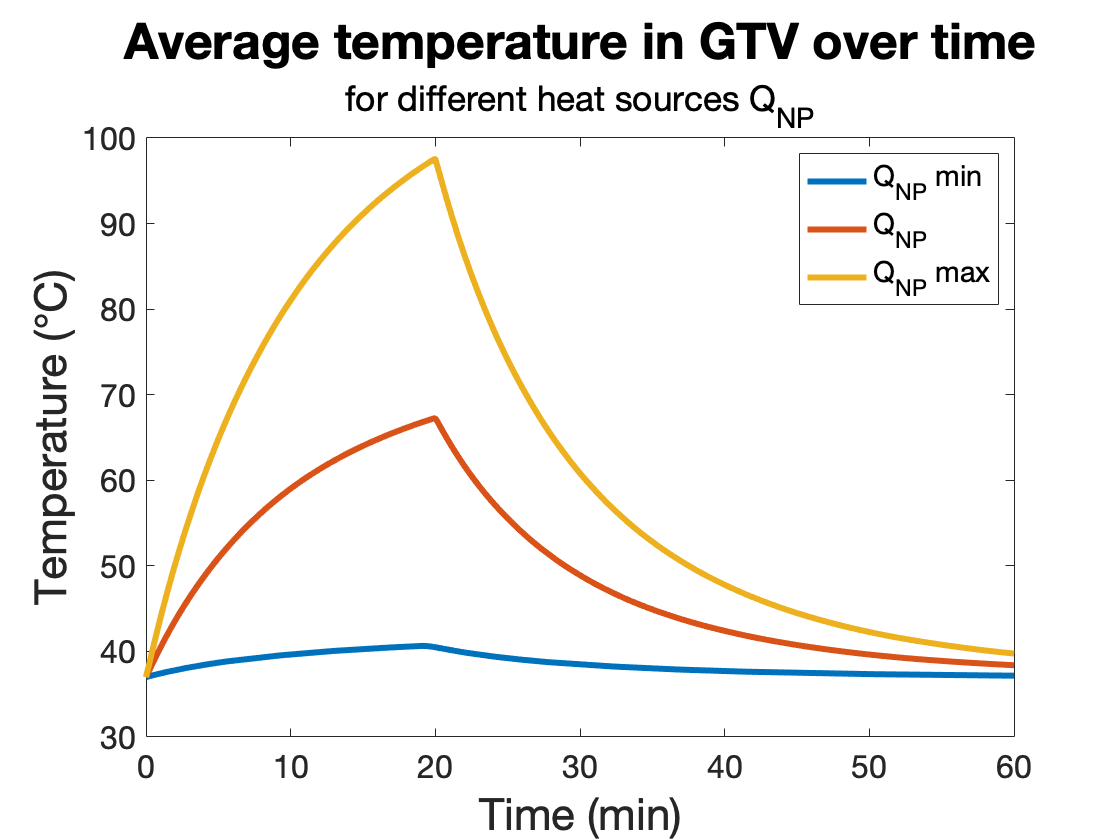

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

figure
plot(runData.timePointsX,Tresults_QNP_min.averageT,'LineWidth',3)
hold on
plot(runData.timePointsX,Tresults_wb_constant.averageT,'LineWidth',3)
plot(runData.timePointsX,Tresults_QNP_max.averageT,'LineWidth',3)
set(gca,'FontSize',16)
title('Average temperature in GTV over time','FontSize',25)
txt = {'for different heat sources Q_{NP}'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("Q_{NP} min","Q_{NP}","Q_{NP} max")
xlim([0 60])

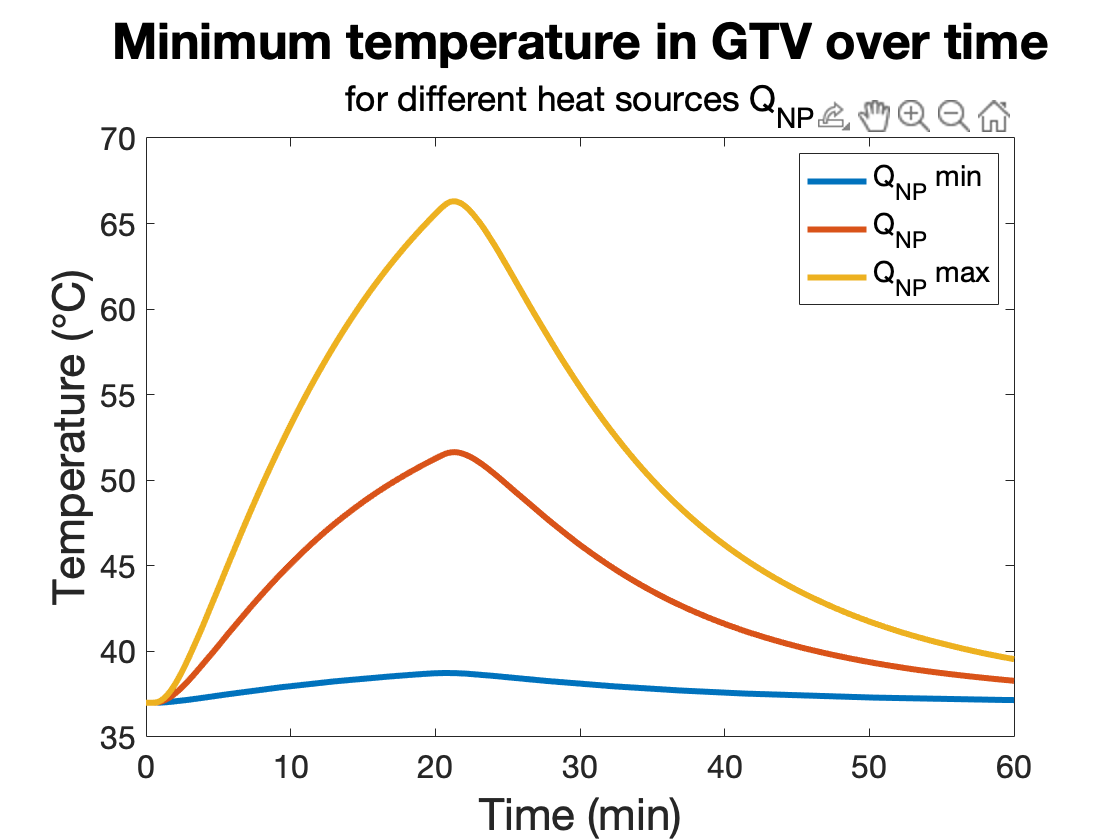


figure
plot(runData.timePointsX,Tresults_QNP_min.minT,'LineWidth',3)
hold on
plot(runData.timePointsX,Tresults_wb_constant.minT,'LineWidth',3)
plot(runData.timePointsX,Tresults_QNP_max.minT,'LineWidth',3)
set(gca,'FontSize',16)
title('Minimum temperature in GTV over time','FontSize',25)
txt = {'for different heat sources Q_{NP}'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("Q_{NP} min","Q_{NP}","Q_{NP} max")
xlim([0 60])

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

## k min max

Tresults_k_min = load('Tresults_k_min.mat');
Tresults_wb_constant = load('Tresults_wb_constant.mat');
Tresults_k_max = load('Tresults_k_max.mat');

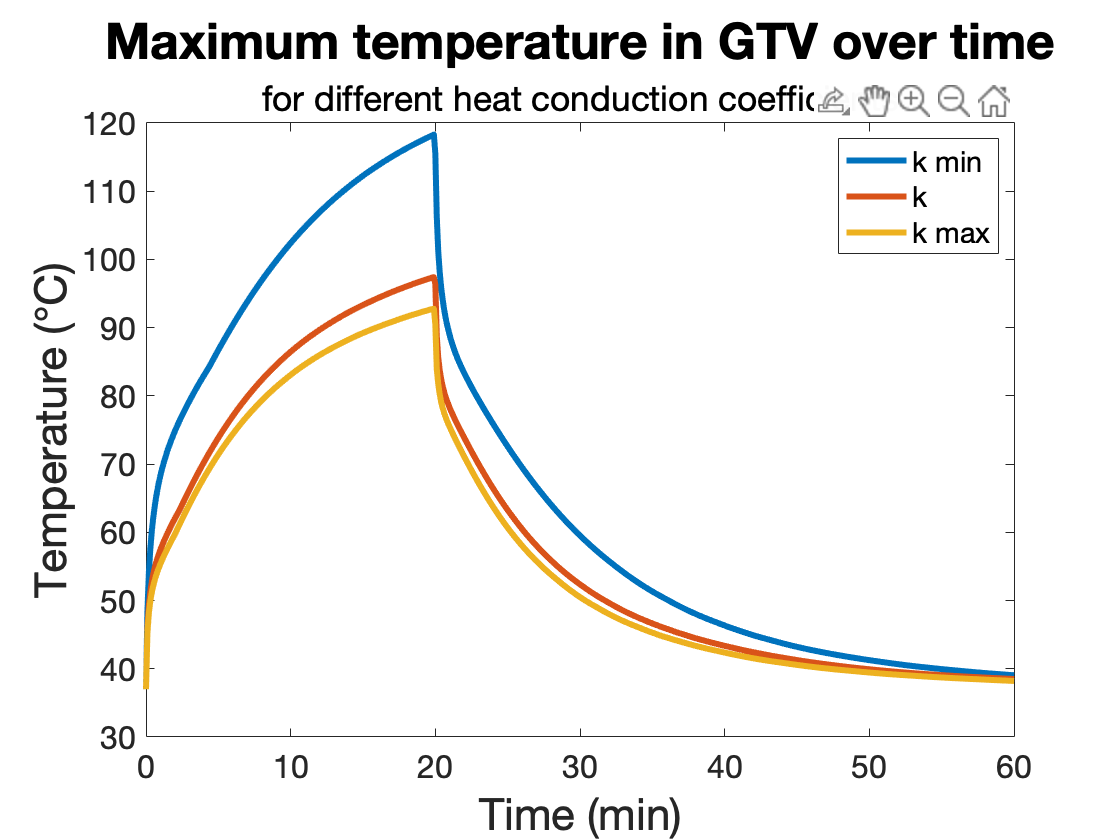


runData.timePointsX = 0:0.1:90;
figure
plot(runData.timePointsX,Tresults_k_min.solMax,'LineWidth',3)
hold on
plot(runData.timePointsX,Tresults_wb_constant.solMax,'LineWidth',3)
plot(runData.timePointsX,Tresults_k_max.solMax,'LineWidth',3)
set(gca,'FontSize',16)
title('Maximum temperature in GTV over time','FontSize',25)
txt = {'for different heat conduction coefficients'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("k min","k","k max")
xlim([0 60])

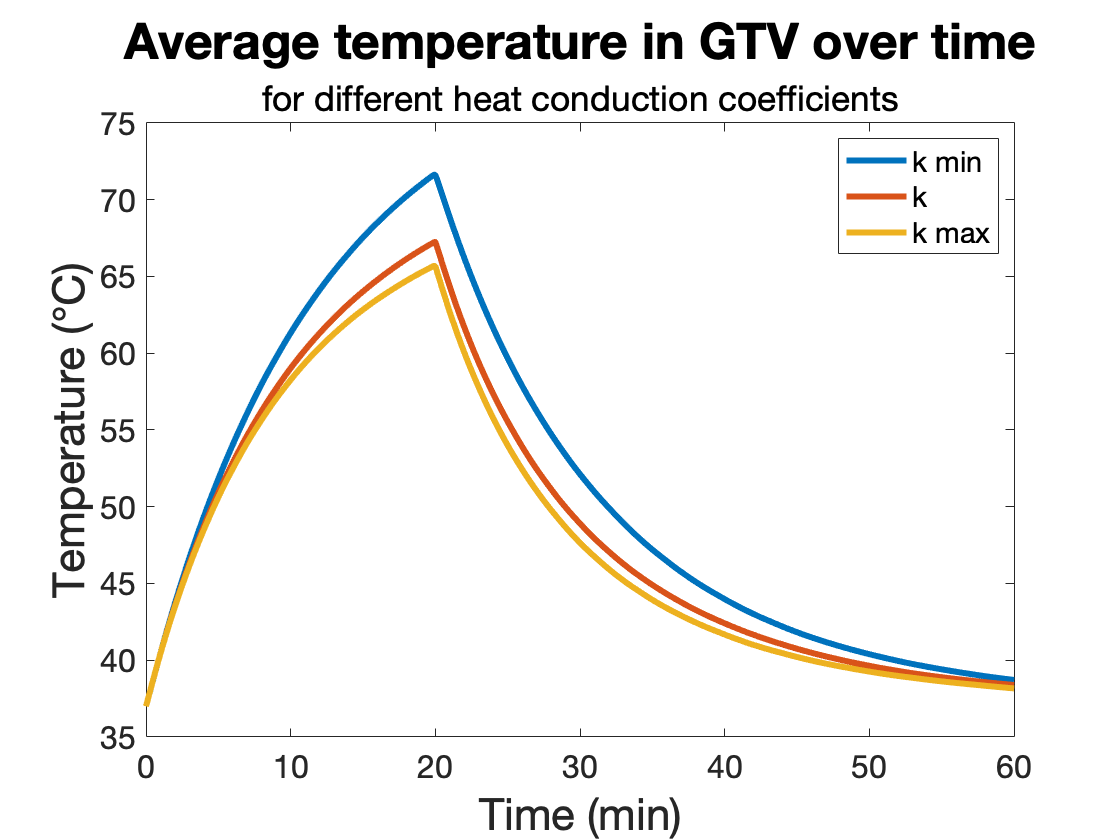

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

figure
plot(runData.timePointsX,Tresults_k_min.averageT,'LineWidth',3)
hold on
plot(runData.timePointsX,Tresults_wb_constant.averageT,'LineWidth',3)
plot(runData.timePointsX,Tresults_k_max.averageT,'LineWidth',3)
set(gca,'FontSize',16)
title('Average temperature in GTV over time','FontSize',25)
txt = {'for different heat conduction coefficients'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("k min","k","k max")
xlim([0 60])

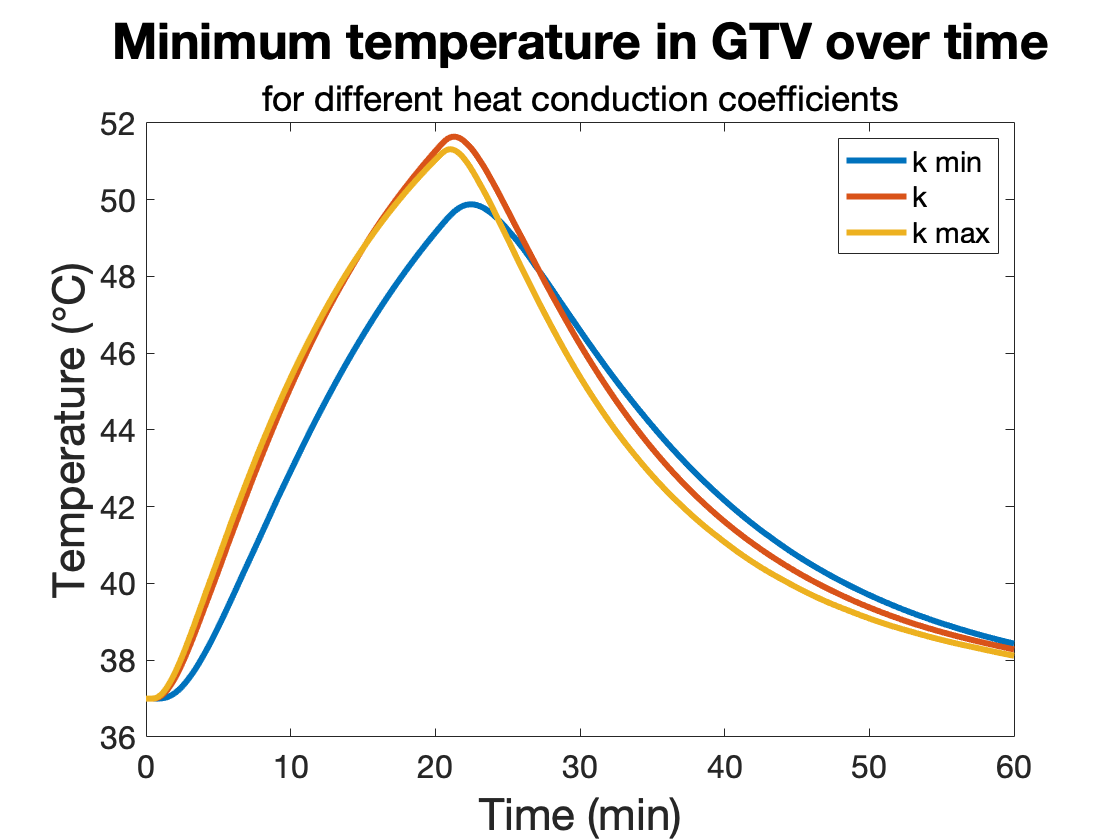


figure
plot(runData.timePointsX,Tresults_k_min.minT,'LineWidth',3)
hold on
plot(runData.timePointsX,Tresults_wb_constant.minT,'LineWidth',3)
plot(runData.timePointsX,Tresults_k_max.minT,'LineWidth',3)
set(gca,'FontSize',16)
title('Minimum temperature in GTV over time','FontSize',25)
txt = {'for different heat conduction coefficients'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("k min","k","k max")
xlim([0 60])

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

## Wb min max

Tresults_wb_min = load('Tresults_wb_min.mat');
Tresults_wb_constant = load('Tresults_wb_constant.mat');
Tresults_wb_max = load('Tresults_wb_max.mat');

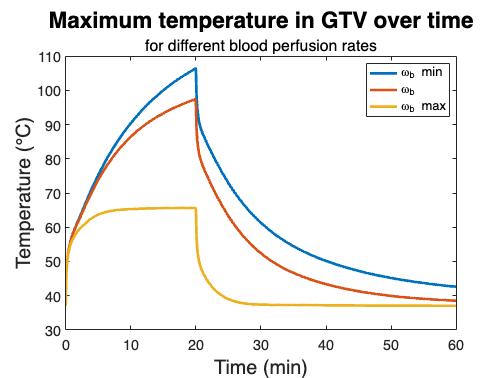


runData.timePointsX = 0:0.1:90;
figure
plot(runData.timePointsX,Tresults_wb_min.solMax,'LineWidth',3)
hold on
plot(runData.timePointsX,Tresults_wb_constant.solMax,'LineWidth',3)
plot(runData.timePointsX,Tresults_wb_max.solMax,'LineWidth',3)
set(gca,'FontSize',16)
title('Maximum temperature in GTV over time','FontSize',25)
txt = {'for different blood perfusion rates'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("\omega_b min","\omega_b","\omega_b max")
xlim([0 60])

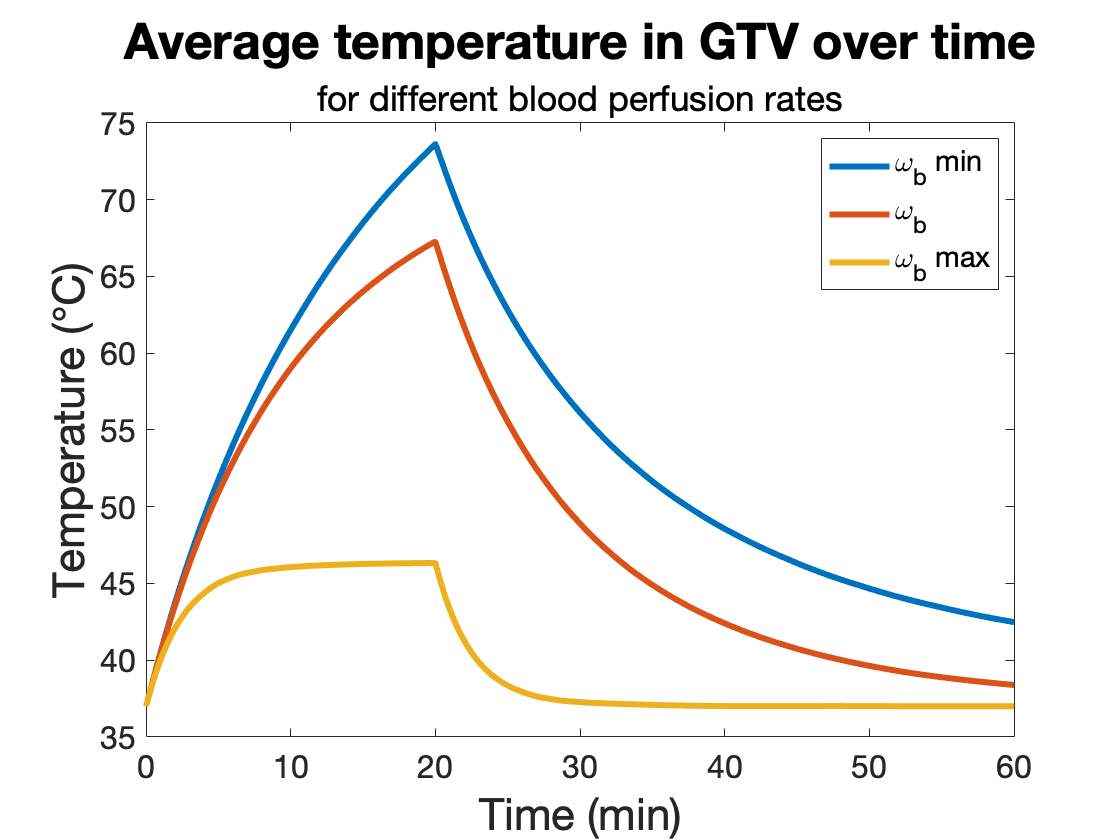

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

figure
plot(runData.timePointsX,Tresults_wb_min.averageT,'LineWidth',3)
hold on
plot(runData.timePointsX,Tresults_wb_constant.averageT,'LineWidth',3)
plot(runData.timePointsX,Tresults_wb_max.averageT,'LineWidth',3)
set(gca,'FontSize',16)
title('Average temperature in GTV over time','FontSize',25)
txt = {'for different blood perfusion rates'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("\omega_b min","\omega_b","\omega_b max")
xlim([0 60])

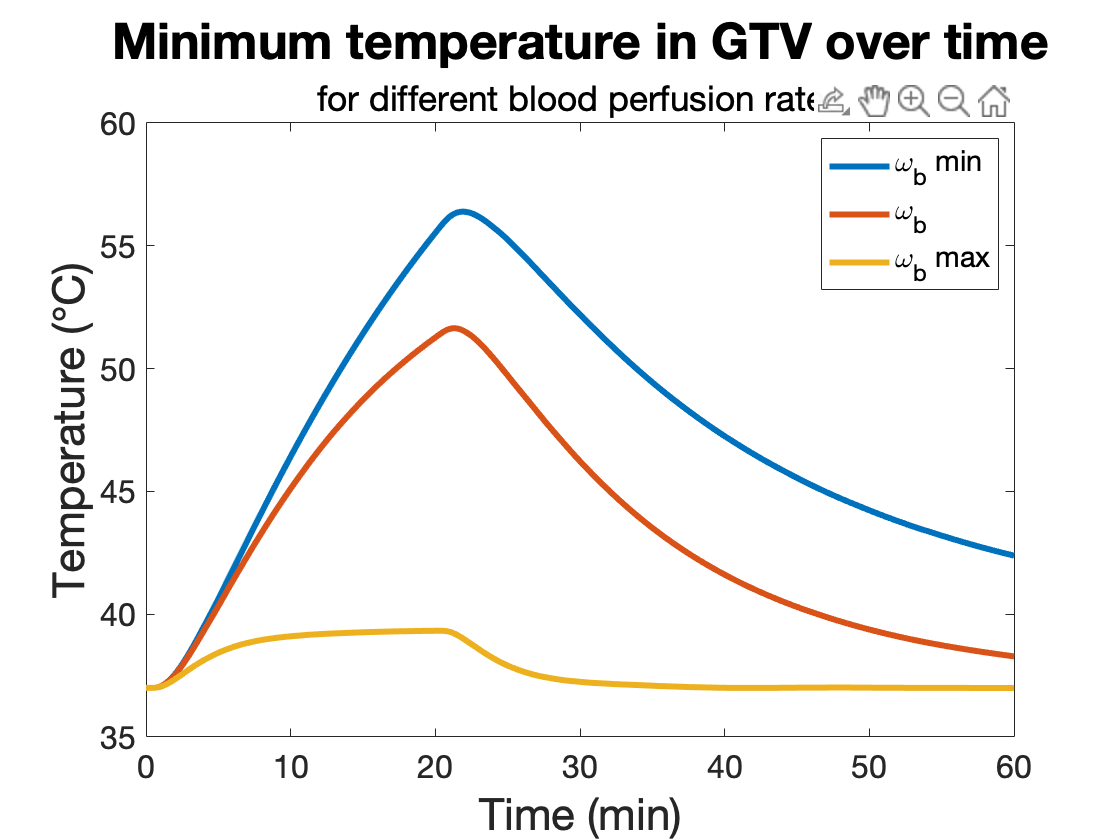


figure
plot(runData.timePointsX,Tresults_wb_min.minT,'LineWidth',3)
hold on
plot(runData.timePointsX,Tresults_wb_constant.minT,'LineWidth',3)
plot(runData.timePointsX,Tresults_wb_max.minT,'LineWidth',3)
set(gca,'FontSize',16)
title('Minimum temperature in GTV over time','FontSize',25)
txt = {'for different blood perfusion rates'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("\omega_b min","\omega_b","\omega_b max")
xlim([0 60])

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);





## Wb functions

Tresults_wb_constant = load('Tresults_wb_constant.mat');
Tresults_XZ_wb_lin = load('Tresults_XZ_wb_lin.mat');
Tresults_XZ_wb_F = load('Tresults_XZ_wb_F.mat');

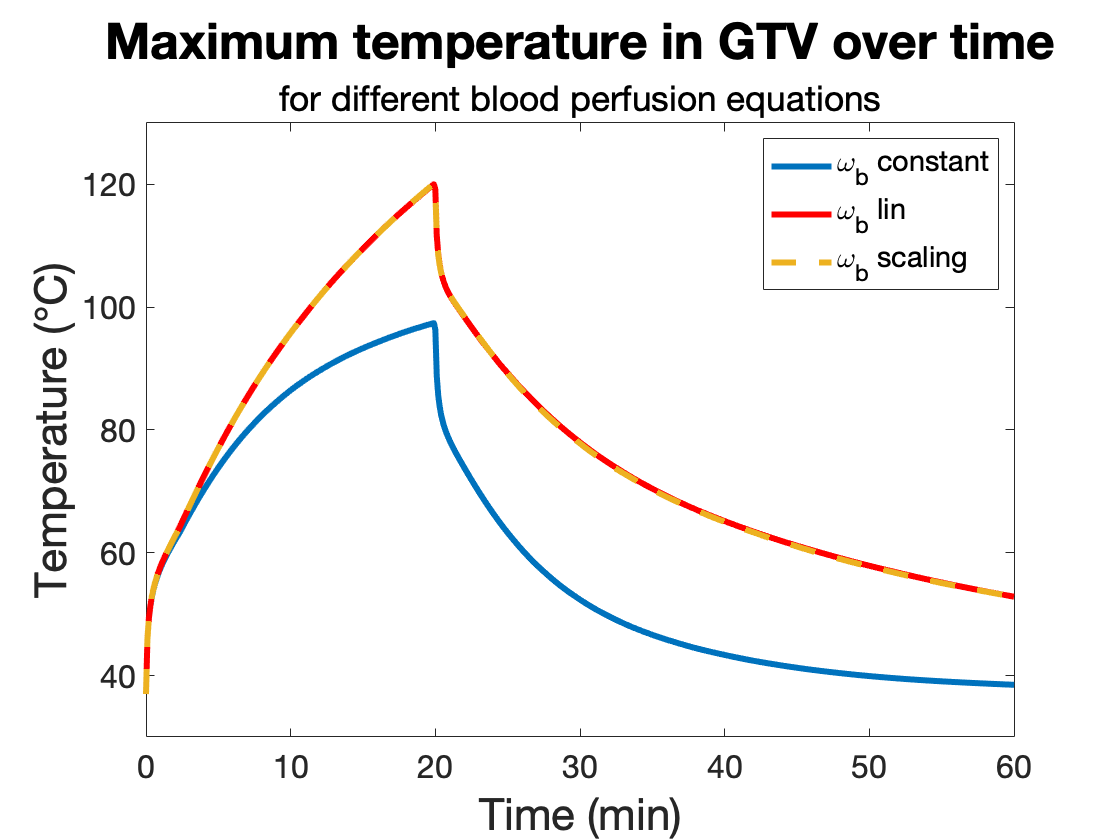


runData.timePointsX = 0:0.1:90;
runData.timePoints = 0:0.1:60;

figure
plot(runData.timePointsX,Tresults_wb_constant.solMax,'LineWidth',3)
hold on
plot(runData.timePoints,Tresults_XZ_wb_lin.solMax,'LineWidth',3,'Color','r')
plot(runData.timePoints,Tresults_XZ_wb_F.solMax,'LineWidth',3,'LineStyle','--')
set(gca,'FontSize',16)
title('Maximum temperature in GTV over time','FontSize',25)
txt = {'for different blood perfusion equations'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("\omega_b constant","\omega_b lin","\omega_b scaling")
xlim([0 60])

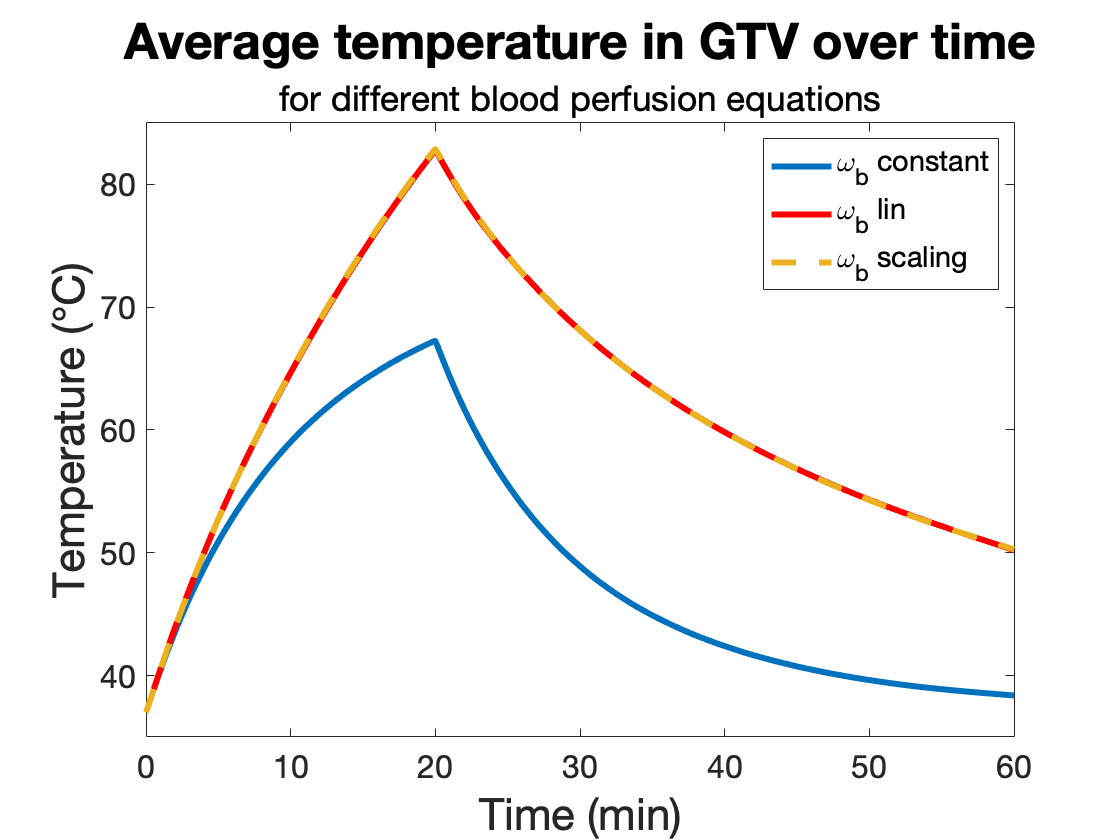

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);

figure
plot(runData.timePointsX,Tresults_wb_constant.averageT,'LineWidth',3)
hold on
plot(runData.timePoints,Tresults_XZ_wb_lin.averageT,'LineWidth',3,'Color','r')
plot(runData.timePoints,Tresults_XZ_wb_F.averageT,'LineWidth',3,'LineStyle','--')
set(gca,'FontSize',16)
title('Average temperature in GTV over time','FontSize',25)
txt = {'for different blood perfusion equations'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("\omega_b constant","\omega_b lin","\omega_b scaling")
xlim([0 60])

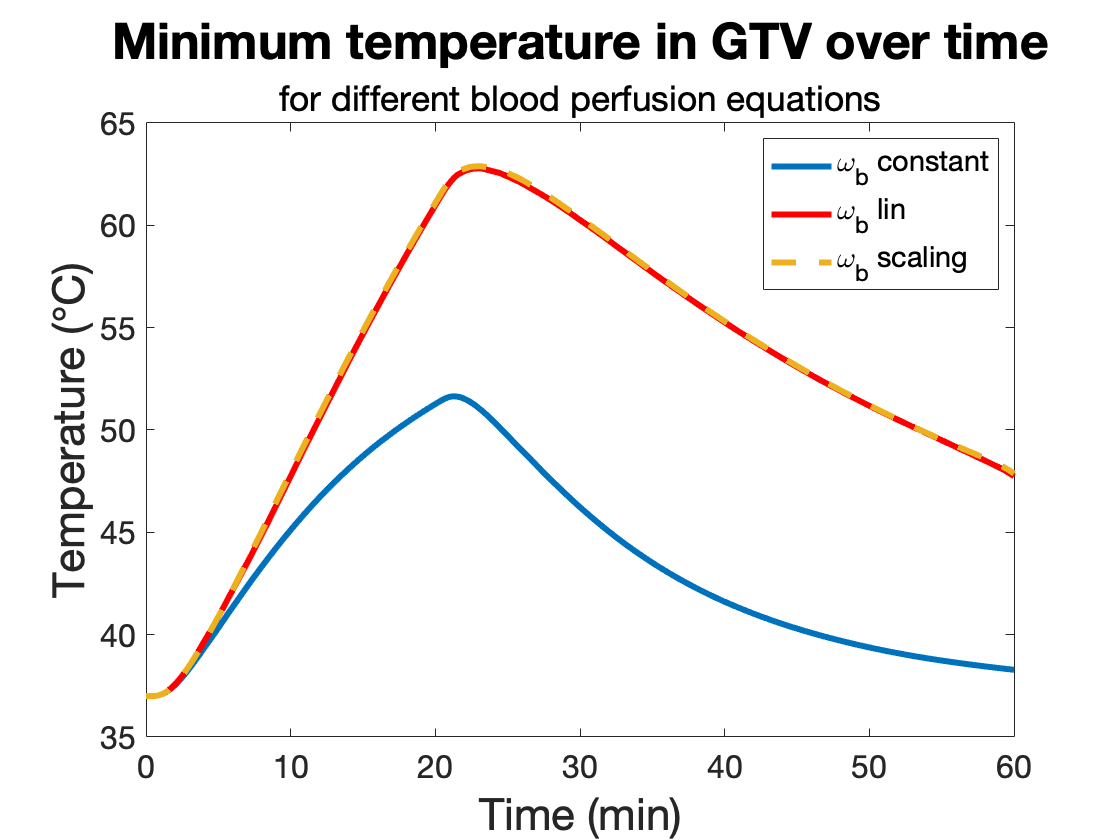


figure
plot(runData.timePointsX,Tresults_wb_constant.minT,'LineWidth',3)
hold on
plot(runData.timePoints,Tresults_XZ_wb_lin.minT,'LineWidth',3,'Color','r')
plot(runData.timePoints,Tresults_XZ_wb_F.minT,'LineWidth',3,'LineStyle','--')
set(gca,'FontSize',16)
title('Minimum temperature in GTV over time','FontSize',25)
txt = {'for different blood perfusion equations'};
subtitle(txt,'FontSize',25)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',22)
xlabel("Time (min)",'FontSize',22) 
legend("\omega_b constant","\omega_b lin","\omega_b scaling")
xlim([0 60])

%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);


## XZ YZ comparison

figure
plot(runData.timePointsX,Tresults_XZ_default.solMax,'LineWidth',3,'Color',"#0000FF")
hold on
plot(runData.timePointsX,Tresults_XZ_default.averageT,'LineWidth',3,'Color',"#0072BD")
plot(runData.timePointsX,Tresults_XZ_default.minT,'LineWidth',3,'Color',"#4DBEEE")
plot(runData.timePoints,Tresults_YZ_default.solMax,'LineWidth',3,'Color',"#A2142F")
plot(runData.timePoints,Tresults_YZ_default.averageT,'LineWidth',3,'Color',"#D95319")
plot(runData.timePoints,Tresults_YZ_default.minT,'LineWidth',3,'Color',"#EDB120")
title('Temperature in GTV over time','FontSize',22)
txt = {'for XZ and YZ plane'};
subtitle(txt,'FontSize',22)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',17)
xlabel("Time (min)",'FontSize',17) 
legend("XZ T max","XZ T average","XZ T min","YZ T max","YZ T average","YZ T min")
%clb = colorbar;
%set(get(clb,'label'),'string',['Temperature (' char(176) 'C)'],'FontSize',22);
set(gca,'FontSize',15)

